Load Parameters

DIR = 'C:\Users\Sohaib\OneDrive - The Cooper Union for the Advancement of Science and Art\Senior Spring\Data Driven Methods\SVD\Airfoil Analysis';

paramsFile = fullfile(DIR,'airfoilDNS_parameters.h5');


dt_field = h5read(paramsFile,'/dt_field'); % timestep for field variables (velocity and vorticity)
dt_force = h5read(paramsFile,'/dt_force'); % timestep for scalar quantities
Re = h5read(paramsFile,'/Re');
FreqsAll = h5read(paramsFile,'/frequencies'); % pitching frequencies
alpha_p = h5read(paramsFile,'/alpha_p'); % pitching amplitude (deg)
alpha_0s = h5read(paramsFile,'/alpha_0s'); % base angles of attack (deg) (25 and 30)
pich_axis = h5read(paramsFile,'/pitch_axis'); % 0.5, midchord pitching

Load grid and velocities

BaseAngle = 30;
freq = 0.35;
tstep = 1;

filenameGrid = fullfile(DIR,'airfoilDNS_grid.h5');
filename = fullfile(DIR,'airfoilDNS_a25f0p35.h5');

x = h5read(filenameGrid,'/x');
y = h5read(filenameGrid,'/y');
nx = length(x);
ny = length(y);

ux = h5read(filename,'/ux'); % streamwise velocity
uy = h5read(filename,'/uy'); % transverse velocity

xa = h5read(filename,'/xa');
ya = h5read(filename,'/ya');
t_field = h5read(filename,'/t_field');
t_force = h5read(filename,'/t_force');
nt = length(t_field);

Reshape and compute SVD

uxreshape = reshape(ux,nx*ny,nt);
uyreshape = reshape(uy,nx*ny,nt);
data = [uxreshape;uyreshape];

data_mean = mean(data,2);
data = data-data_mean*ones(1,nt);

[U,S,V] = svd(data, "econ");

Plot eigenvalues

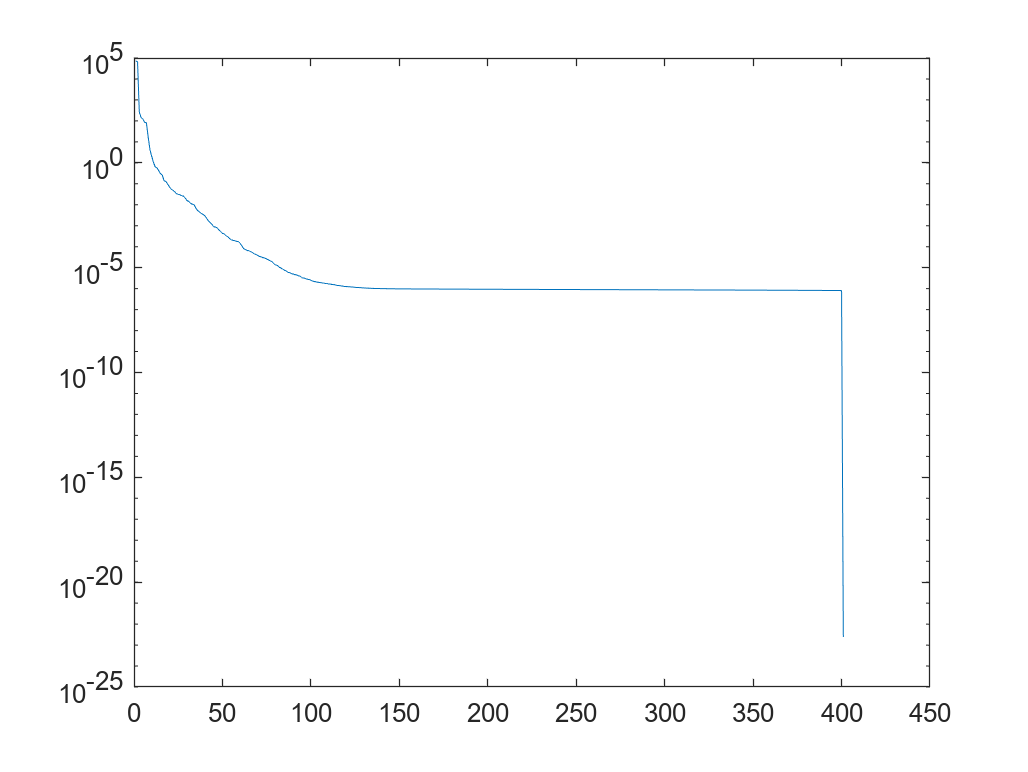

eigs = diag(S).^2;
indices = 1:length(eigs);

ylim([10^-1 10^6])
%xlim([0 length(eigs)])

xlabel("index")
ylabel("eigenvalue")

title("Eigenvalues of Data")

semilogy(indices, eigs)

Plot spatial modes

cols = 2;
rows = 3;

num_plots = cols * rows;

[X,Y] = meshgrid(x, y);


size(U, 1)

ans = 358202

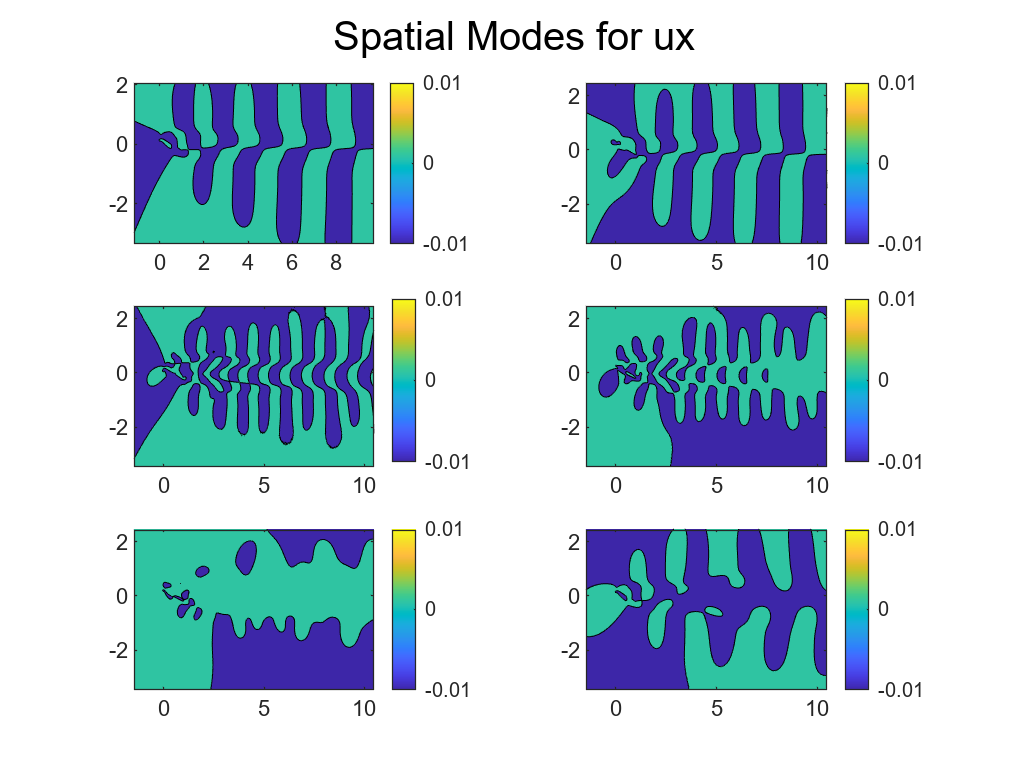

half = int32(size(U, 1)/2);

figure

for i = 1:num_plots
    Ux_field = reshape(U(1:half,i), [nx, ny]);
    subplot(rows, cols, i)
    contourf(X, Y, Ux_field.', -0.1:0.1:0.001)
    clim([-0.01 0.01]);
    colorbar;
end

sgtitle('Spatial Modes for ux')

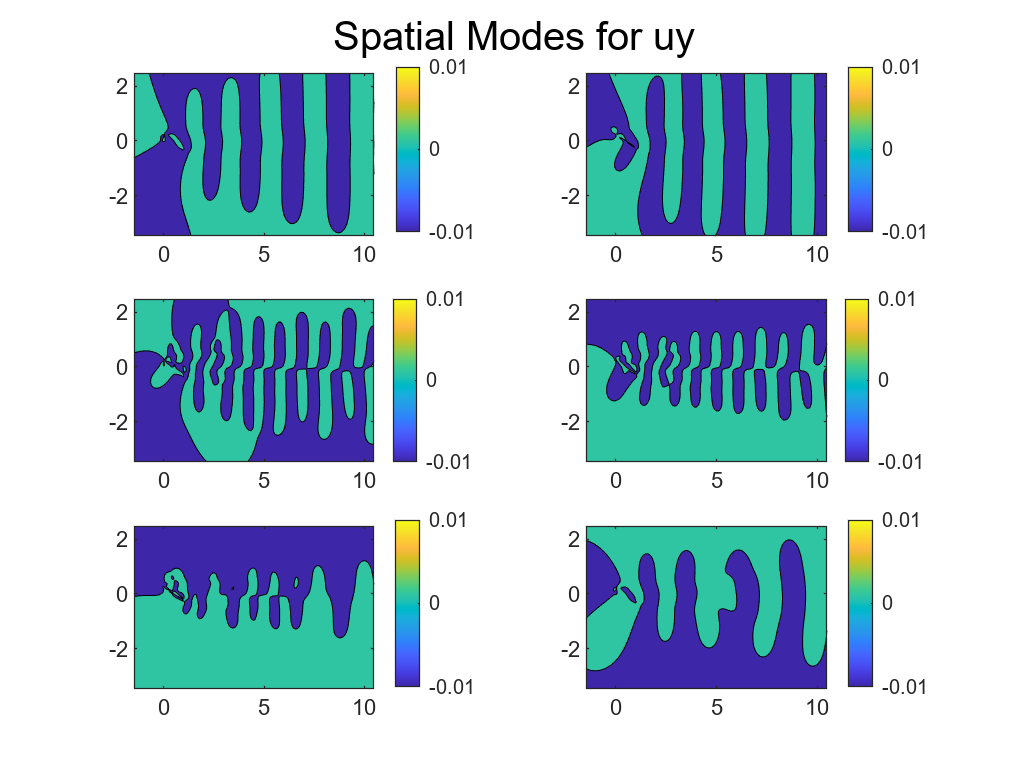


figure

for i = 1:num_plots
    Uy_field = reshape(U(half+1:end,i), [nx, ny]);
    subplot(rows, cols, i)
    contourf(X, Y, Uy_field.', -0.1:0.1:0.001)
    clim([-0.01 0.01]);
    colorbar;
end


sgtitle('Spatial Modes for uy')

Plot temporal amplitudes

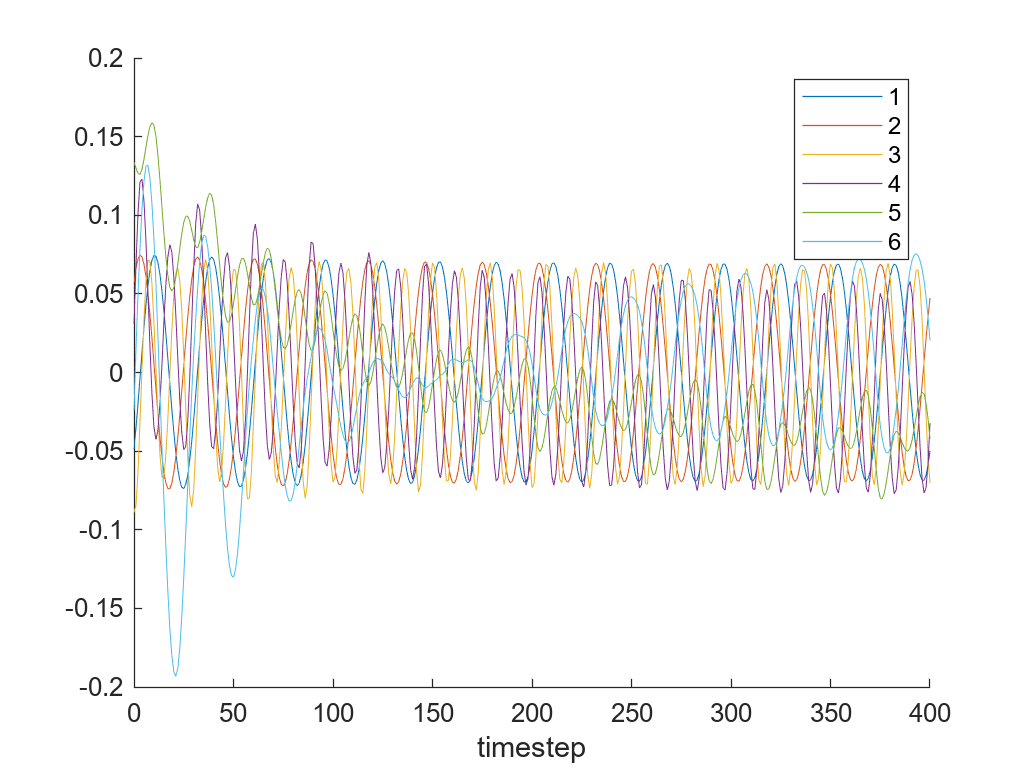

temporal_amplitudes = V(:, 1:num_plots);



figure
hold on

xlabel("timestep")
time = 0:(size(temporal_amplitudes, 1)-1);
for i = 1:num_plots
    plot(time, temporal_amplitudes(:, i))
end
legend('1','2','3','4','5','6')

Reconstructing snapshots

r = [2, 4, 6];

videofile = "FluidFlowReconstruction.avi";
v = VideoWriter(videofile, 'Motion JPEG AVI'); % Choose your desired format
v.FrameRate = 10; % Adjust frame rate as needed
open(v);

for t = 1:nt
    % Create a new figure for each frame to ensure consistent sizing
    fig = figure('Units', 'pixels', 'Position', [100, 100, 1920, 1080], 'Visible', 'off');

    % Original flow plot
    subplot(1, 4, 1);
    imagesc(x, y, squeeze(uy(:,:,t))');
    axis equal tight;
    title('Original Flow');
    colorbar;
    for i = 1:length(r)
        Ur = U(:,1:r(i));
        Sr = S(1:r(i), 1:r(i));
        Vr = V(:, 1:r(i));
        mean = data_mean*ones(1,nt);
        data_approx_womean =  Ur * Sr * Vr';
        data_approx = data_approx_womean + mean;
        uy_approx =reshape(data_approx(nx*ny+1:end, nt), ny, nx);
        subplot(1, 4, i+1);
        imagesc(x, y, uy_approx');
        axis equal tight;
        title(['Reconstruction r=', num2str(r)]);
        colorbar;
    end
    drawnow;

    % Capture and write frame
    frame = getframe(fig);
    writeVideo(v, frame);

    % Close the figure to free up memory
    close(fig);
end
close(v);